# Lab 1 - Introduction to Membrane Properties

## 1). Equilibrium Potential

### I). Behavior of Potassium Ions

- $K^+$only

- 
$$C_{in}=130~mM,~~C_{out}=3~mM$$


% Variables
[z, Cin, Cout] = deal(+1, 130, 3);

#### A). When Vm = 0 mV

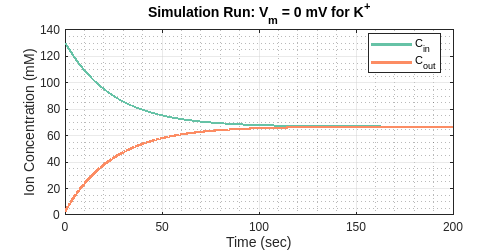

% Run simulation
Vm = 0;
[time, Cin_new, Cout_new] = npe('z', z, 'Cin' ,Cin, 'Cout', Cout, 'Vm', Vm);

% Plot results
plot_(time, Cin_new, Cout_new);
title("Simulation Run: V_m = 0 mV for K^+");

- Over time, the concentrations of ions inside and outside the cell reach equilibrium at a concentration of about $66.5~\text{mM}$.

- Since the membrane is permeable to potassium and there is no voltage difference, the potassium ions diffuse freely across the membrane until the system reaches equilibrium.

#### B). When Vm = -40 mV

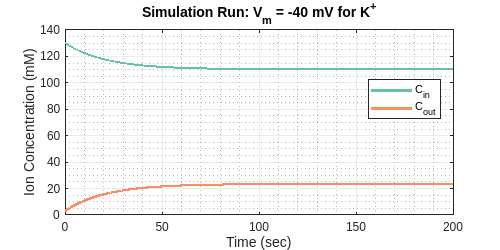

% Run simulation
Vm = -40;
[time, Cin_new, Cout_new] = npe('z', z, 'Cin' ,Cin, 'Cout', Cout, 'Vm', Vm);

% Plot results
plot_(time, Cin_new, Cout_new);
title("Simulation Run: V_m = -40 mV for K^+");

- Over time, the concentrations inside and outside the cell reach steady state values of about 110 mM and 23 mM respectively.

- In this scenario, the ions diffuse across the membrane, along their concentration gradient, but the negative membrane potential, causes more potassium ions to remain in the cell.

#### C). Vm when Concentration Gradient is Constant

% Calculate nernst potential
E_k = nernst('z', z, 'Cout', Cout, 'Cin', Cin);
fprintf('The Nernst potential for Potassium, E_K = %.2f mV', E_k)

The Nernst potential for Potassium, E_K = -96.74 mV

% Parameter sweep to find Vm that keeps concentration gradient constant
volts = linspace(-100, 100, 1000);
Vm_const = NaN;

for i = 1:numel(volts)
    % Run simulation
    Vm = volts(i);
    [time, Cin_new, Cout_new] = npe('z', z, 'Cin', Cin, 'Cout', Cout, 'Vm', Vm);

    % See if steady state value is the same as initial
    I = allclose(Cin_new(end-200:end), Cin_new(1));
    J = allclose(Cout_new(end-200:end), Cout_new(1));
    
    % If value is constant, store it and exit the loop
    if isnan(Vm_const) && I && J
        Vm_const = Vm;
        break
    end
end

% Print & plot
fprintf('The concentration gradient is constant at Vm = %.2f mV', Vm_const)

The concentration gradient is constant at Vm = -97.00 mV

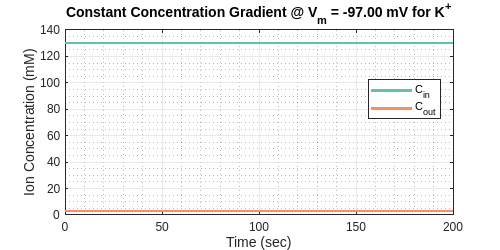

plot_(time, Cin_new, Cout_new)
title(sprintf('Constant Concentration Gradient @ V_m = %.2f mV for K^+', Vm_const))

- The Vm value obtained through simulation was approximately equal to the theoretical Nernst poetential for potassium.

#### D). When Extracellular $K^+$Concentration Increases from 3 mM to 10 mM

% Calculate nernst potential
Cout = 10; 
E_k = nernst('z', z, 'Cout', Cout, 'Cin', Cin);
fprintf('The Nernst potential for Potassium, E_K = %.2f mV', E_k)

The Nernst potential for Potassium, E_K = -65.84 mV

### II). Behavior of Sodium Ions

- $Na^+$only

- 
$$C_{in}=10~mM,~~C_{out}=124~mM$$


% Variables
[z, Cin, Cout] = deal(+1, 10, 124);

#### E). When Vm = 0 mV

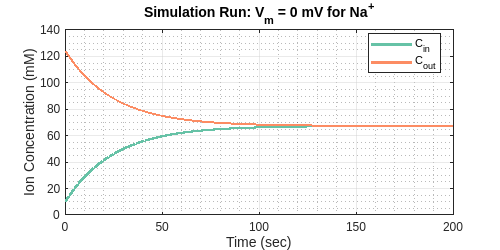

% Run simulation
Vm = 0;
[time, Cin_new, Cout_new] = npe('z', z, 'Cin' ,Cin, 'Cout', Cout, 'Vm', Vm);

% Plot results
plot_(time, Cin_new, Cout_new);
title("Simulation Run: V_m = 0 mV for Na^+");

- Over time, the concentrations of ions inside and outside the cell reach equilibrium at a concentration of about $67~\text{mM}$.

- Since the membrane is permeable to sodium and there is no voltage difference, the sodium ions diffuse freely across the membrane until the system reaches equilibrium.

#### F). When Vm = -40 mV

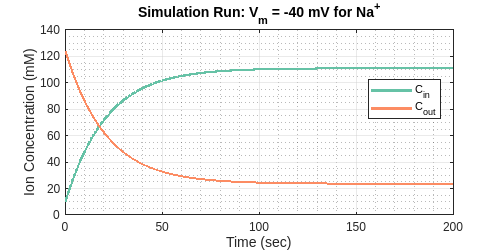

% Run simulation
Vm = -40;
[time, Cin_new, Cout_new] = npe('z', z, 'Cin' ,Cin, 'Cout', Cout, 'Vm', Vm);

% Plot results
plot_(time, Cin_new, Cout_new);
title("Simulation Run: V_m = -40 mV for Na^+");

- Since the intracellular compartment is negatively charged in comparison to the extracellular compartment, more sodium ions diffuse into the intracellular compartment resulting in C_in increasing until it reaches about 110 mM and C_out decreasing until it reaches about 23 mM.

#### G). Vm when Concentration Gradient is Constant

% Calculate nernst potential
E_Na = nernst('z', z, 'Cout', Cout, 'Cin', Cin);
fprintf('The Nernst potential for Sodium, E_Na = %.2f mV', E_Na)

The Nernst potential for Sodium, E_Na = 64.62 mV

% Parameter sweep to find Vm that keeps concentration gradient constant
volts = linspace(-100, 100, 1000);
Vm_const = NaN;

for i = 1:numel(volts)
    % Run simulation
    Vm = volts(i);
    [time, Cin_new, Cout_new] = npe('z', z, 'Cin', Cin, 'Cout', Cout, 'Vm', Vm);

    % See if steady state value is the same as initial
    I = allclose(Cin_new(end-200:end), Cin_new(1));
    J = allclose(Cout_new(end-200:end), Cout_new(1));
    
    % If value is constant, store it and exit the loop
    if isnan(Vm_const) && I && J
        Vm_const = Vm;
        break
    end
end

% Print & plot
fprintf('The concentration gradient is constant at Vm = %.2f mV', Vm_const)

The concentration gradient is constant at Vm = 64.36 mV

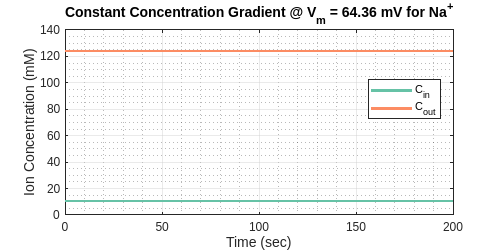

plot_(time, Cin_new, Cout_new)
title(sprintf('Constant Concentration Gradient @ V_m = %.2f mV for Na^+', Vm_const))

- The Vm value obtained through simulation was approximately equal to the theoretical Nernst poetential for sodium.

### III). Behavior of Chloride Ions

- $Cl^-$only

- 
$$C_{in}=30~mM,~~C_{out}=130~mM$$


% Variables
[z, Cin, Cout] = deal(-1, 30, 130);

#### H). When Vm = 0 mV

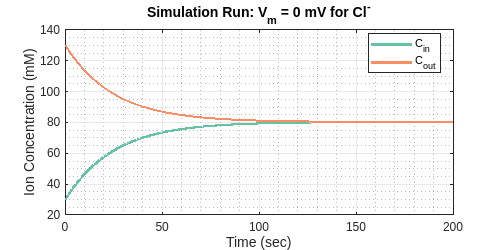

% Run simulation
Vm = 0;
[time, Cin_new, Cout_new] = npe('z', z, 'Cin' ,Cin, 'Cout', Cout, 'Vm', Vm);

% Plot results
plot_(time, Cin_new, Cout_new);
title("Simulation Run: V_m = 0 mV for Cl^-");

- Over time, the concentrations of ions inside and outside the cell reach equilibrium at a concentration of about $80~\text{mM}$.

- Since the membrane is permeable to chloride ions and there is no voltage difference, the chloride ions diffuse freely across the membrane until the system reaches equilibrium.

#### I). When Vm = -40 mV

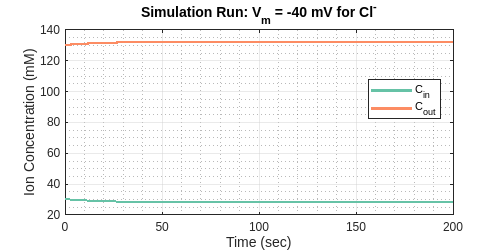

% Run simulation
Vm = -40;
[time, Cin_new, Cout_new] = npe('z', z, 'Cin' ,Cin, 'Cout', Cout, 'Vm', Vm);

% Plot results
plot_(time, Cin_new, Cout_new);
title("Simulation Run: V_m = -40 mV for Cl^-");

- The negative membrane potential causes  some chloride ions to leave the cell, resulting in  a slight increase in C_out and a slight decrease in C_in at equilibrium.

#### J). Vm when Concentration Gradient is Constant

% Calculate nernst potential
E_k = nernst('z', z, 'Cout', Cout, 'Cin', Cin);
fprintf('The Nernst potential for Chloride, E_K = %.2f mV', E_k)

The Nernst potential for Chloride, E_K = -37.64 mV

% Parameter sweep to find Vm that keeps concentration gradient constant
volts = linspace(-100, 100, 1000);
Vm_const = NaN;

for i = 1:numel(volts)
    % Run simulation
    Vm = volts(i);
    [time, Cin_new, Cout_new] = npe('z', z, 'Cin', Cin, 'Cout', Cout, 'Vm', Vm);

    % See if steady state value is the same as initial
    I = allclose(Cin_new(end-200:end), Cin_new(1));
    J = allclose(Cout_new(end-200:end), Cout_new(1));
    
    % If value is constant, store it and exit the loop
    if isnan(Vm_const) && I && J
        Vm_const = Vm;
        break
    end
end

% Print & plot
fprintf('The concentration gradient is constant at Vm = %.2f mV', Vm_const)

The concentration gradient is constant at Vm = -37.94 mV

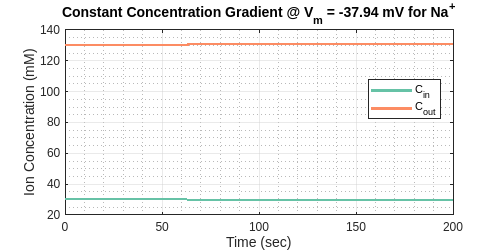

plot_(time, Cin_new, Cout_new)
title(sprintf('Constant Concentration Gradient @ V_m = %.2f mV for Na^+', Vm_const))

- The Vm value obtained through simulation was approximately equal to the theoretical Nernst poetential for chloride ions.

### III). Larger Extracellular Compartment (Potassium Ions)

- `vol_o = 10`

- $Na^+$only

- 
$$C_{in}=10~mM,~~C_{out}=124~mM$$


% Variables
[z, Cin, Cout, vol_o] = deal(+1, 10, 124, 10);

#### K). When Vm = 0 mV

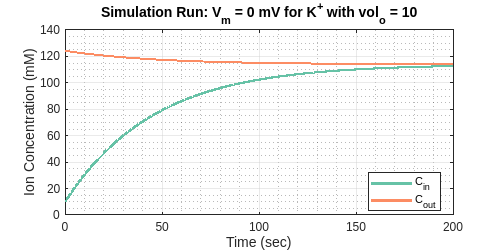

% Run simulation
Vm = 0;
[time, Cin_new, Cout_new] = npe('z', z, 'Cin' ,Cin, 'Cout', Cout, 'Vm', Vm, 'vol_o', vol_o);

% Plot results
plot_(time, Cin_new, Cout_new);
title("Simulation Run: V_m = 0 mV for K^+ with vol_o = 10");

- Over time, C_out decreases and C_in increases; both appear to converge at about 114 mM at equilibrium.

- Due to the difference in volume between the compartments, the concentration changes are no longer proportional as in previous problems.

- Since the extracellular compartment is much larger than the intracellular one, there are a lot more sodium ions in the extracellular compartment at the start of the simulation.

- WHen the simulation begins, sodium ions diffuse across the membrane, causing a drastic increase in C_in - which is more sensitive to changes in the number of ions  - and a more gradual decrease in C_out.

#### L). When Vm = -40 mV

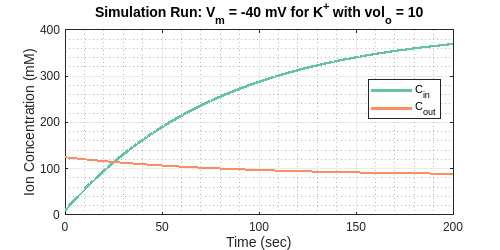

% Run simulation
Vm = -40;
[time, Cin_new, Cout_new] = npe('z', z, 'Cin' ,Cin, 'Cout', Cout, 'Vm', Vm, 'vol_o', vol_o);

% Plot results
plot_(time, Cin_new, Cout_new);
title("Simulation Run: V_m = -40 mV for K^+ with vol_o = 10");

- With the membrane potential at -40mV, the system doesn't appear to reach equilibrium within the simulated time period

- Due to the negative potential, sodium ions diffuse into to cell, and we see a drastic increase in C_in. We also observe a more gradual decrease in C_out due to the presence of more Na+ ions outside the cell.

#### M). Vm when Concentration Gradient is Constant

% Calculate nernst potential
E_Na = nernst('z', z, 'Cout', Cout, 'Cin', Cin);
fprintf('The Nernst potential for sodium, E_Na = %.2f mV', E_Na)

The Nernst potential for sodium, E_Na = 64.62 mV

% Parameter sweep to find Vm that keeps concentration gradient constant
volts = linspace(-100, 100, 1000);
Vm_const = NaN;

for i = 1:numel(volts)
    % Run simulation
    Vm = volts(i);
    [time, Cin_new, Cout_new] = npe('z', z, 'Cin', Cin, 'Cout', Cout, 'Vm', Vm, 'vol_o', vol_o);

    % See if steady state value is the same as initial
    I = allclose(Cin_new(end-200:end), Cin_new(1));
    J = allclose(Cout_new(end-200:end), Cout_new(1));
    
    % If value is constant, store it and exit the loop
    if isnan(Vm_const) && I && J
        Vm_const = Vm;
        break
    end
end

% Print & plot
fprintf('The concentration gradient is constant at Vm = %.2f mV', Vm_const)

The concentration gradient is constant at Vm = 64.36 mV

plot_(time, Cin_new, Cout_new)
title(sprintf('Constant Concentration Gradient @ V_m = %.2f mV for Na^+', Vm_const))

- The Vm value obtained through simulation was approximately equal to the theoretical Nernst poetential for sodium.

## 2). Resting Potential

- Cell permeable to K+, Na+ and Cl-

- Vm influenced by charges and permeabilities of 3 ions

- Permeability range: 0.0001 - 1

% Common Variables
Ci = struct('Na', 10, 'K', 130, 'Cl', 20);
Co = struct('Na', 124, 'K', 3, 'Cl', 130);

% Calculate Nernst potentials for reference
E_K  = nernst('z', +1, 'Cin', Ci.K, 'Cout', Co.K);
E_Na = nernst('z', +1, 'Cin', Ci.Na, 'Cout', Co.Na);
E_Cl = nernst('z', -1, 'Cin', Ci.Cl, 'Cout', Co.Cl);
disp([ ...
  sprintf('Nernst Potentials for Ions:\n'), ...
  sprintf('E_K  = %.2f mV\n', E_K), ...
  sprintf('E_Na = %.2f mV\n', E_Na), ...
  sprintf('E_Cl = %.2f mV', E_Cl) ...
])

Nernst Potentials for Ions:
E_K  = -96.74 mV
E_Na = 64.62 mV
E_Cl = -48.04 mV


### A). P_Cl = 0.0001

#### 1). When P_K is 0.01 and P_Na is 0.001, what happens to the resting potential?

% Parameters
P_Cl = 0.0001;
P_K = 0.01;
P_Na = 0.001;

% Calculation
Vm = ghk('Na', P_Na, 'Cl', P_Cl, 'K', P_K);
fprintf("Vm = %.2f mV", Vm)

Vm = -54.93 mV

- The membrane potential is close to the membrane potential of potassium but is more positive due to the presence of sodium and chloride ions (to a lesser extent due to their low permeability).

#### 2). What if P_Na is changed to 10 times larger than P_K?

% Parameters
P_Na = 10 * P_K;

% Calculation
Vm = ghk('Na', P_Na, 'Cl', P_Cl, 'K', P_K);
fprintf("Vm = %.2f mV", Vm)

Vm = 43.21 mV

- Since the ion with the highest permeability now has a positive Nernst potential, we see a drastic increase in the membrane potential.

#### 3). What is the maximum hyperpolarizing/depolarizing value for each of these two ionic species? 

- Maximum hyperpolarization/depolarization occurs when the membrane is permeable to only a single ion.

- The maximum depolarization caused by sodium is 64.62mV and it occurs when the permeability of potassium is zero.

- The maximum hyperpolarization caused by potassium is -96.74mV and it occurs when the permeability of sodium is zero.

### B). P_Na = 0.001 and P_K = 10 * P_Na

#### 1). How does increasing P_Cl from 0.0001 affect Vm?

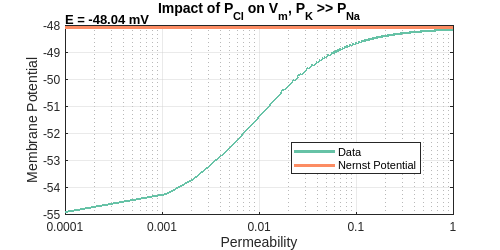

% Parameters
P_Na = 0.001;
P_K = 10 * P_Na;

% Compute Vm across range of P_Cl values
perms = linspace(0.0001, 1, 1000); % Permeabilities
volts = zeros(size(perms)); % Membrane potentials

for i = 1:numel(volts)
    P_Cl = perms(i);
    volts(i) = ghk('Na', P_Na, 'Cl', P_Cl, 'K', P_K);
end

% Visualize results
plot_2(perms, volts, E_Cl);
title('Impact of P_{Cl} on V_m, P_K >> P_{Na}')

- Semi-log axes used to highlight relationship between variables.

- Increasing the permeability of chloride ions resulted in an exponential increase in the membrane potential, ultimately reaching  steady state value close to -48.04mV (the nernst potential for chloride ions).

#### 2). What is the effect of increasing P_Cl if P_Na is much larger than P_K

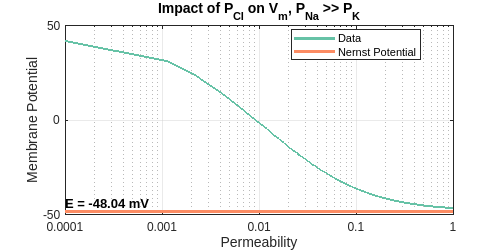

% Parameters
P_K = 0.001;
P_Na = 10 * P_K;

% Compute Vm across range of P_Cl values
perms = linspace(0.0001, 1, 1000); % Permeabilities
volts = zeros(size(perms)); % Membrane potentials

for i = 1:numel(volts)
    P_Cl = perms(i);
    volts(i) = ghk('Na', P_Na, 'Cl', P_Cl, 'K', P_K);
end

% Visualize results
plot_2(perms, volts, E_Cl);
title('Impact of P_{Cl} on V_m, P_{Na} >> P_{K}')

- Semi-log axes used to highlight relationship between variables.

- Increasing the permeability of chloride ions resulted in an exponential decrease in the membrane potential, ultimately approaching a steady state value close to -48.04mV (the nernst potential for chloride ions).

#### 3). Why does PCl affect Vm in this way?

- Increasing the permeability to chloride ions caused the membrane potential to get closer to the nernst potential for chloride. This is because chloride ions are able to move more freely along their concentration gradient.

### C). P_K = 0.01, P_Na = 0.001, P_Cl = 0.0001, and [Cl]_in = 10 mM

% Variables
P_K = 0.01;
P_Na = 0.001;
P_Cl = 0.0001;
Ci.Cl = 10;

#### 1). Record Resting Potential

Vm = ghk('Na', P_Na, 'Cl', P_Cl, 'K', P_K, 'Ci_Cl', Ci.Cl);
fprintf('Vm = %.2f mV', Vm)

Vm = -55.09 mV

#### 2). What happens when P_Cl increases to 0.01

- *Prediction:* If the permeability of chloride ions increases, the resting potential will decrease.

P_Cl = 0.01;
Vm = ghk('Na', P_Na, 'Cl', P_Cl, 'K', P_K, 'Ci_Cl', Ci.Cl);
fprintf('Vm = %.2f mV', Vm)

Vm = -59.86 mV

- *Check: *Results confirm hypothesis.

#### 3). What happens when [Cl]_in = 60 mM and P_Cl increases from 0.0001 to 0.01

- *Prediction: *If the permeability of chloride ions increases, the resting potential will decrease.

Ci.Cl = 60;

P_Cl = 0.0001;
Vm_1 = ghk('Na', P_Na, 'Cl', P_Cl, 'K', P_K, 'Ci_Cl', Ci.Cl);

P_Cl = 0.01;
Vm_2 = ghk('Na', P_Na, 'Cl', P_Cl, 'K', P_K, 'Ci_Cl', Ci.Cl);

fprintf('When P_Cl = 0.0001, Vm = %.2f mV\n     P_Cl = 0.01,   Vm = %.2f mV', Vm_1, Vm_2)

When P_Cl = 0.0001, Vm = -54.28 mV
     P_Cl = 0.01,   Vm = -31.90 mV

- *Check: *Results disprove hypothesis.

### D). Adjust P_Na, P_K, P_Cl so that Vm is close to -80 mV

% Fix permeabilities of sodium and potassium
P_Na = 0;
P_K = 1;

% Concentrations
Ci = struct('Na', 10, 'K', 130, 'Cl', 20);
Co = struct('Na', 124, 'K', 3, 'Cl', 130);

% Vary permeabilities of chloride
arr = linspace(0.01, 0.2, 100);

for i = 1:numel(pots)
    P_Cl = arr(i);
    Vm = ghk('Na', P_Na, 'Cl', P_Cl, 'K', P_K);

    if abs(Vm + 80) <= 1e-2
        break
    end
end

% Results
fprintf('Vm = -80mV when P_Na = 0,\n                P_K  = 1, and\n                P_Cl = %.2f', P_Cl)

Vm = -80mV when P_Na = 0,
                P_K  = 1, and
                P_Cl = 0.20

- There are several combinations possible to produce this resting potential.

- In this case, P_Na is set to 0 (it is furthest away from Vm), P_K is set to 1 (it is closest to Vm), then P_Cl is adjusted to obtain the desired Vm.

## 3). Summary Questions

#### 1). What determines the equilibrium potential for an ion across a barrier? 

- The equilibrium potential for an ion depends on the temperature, charge of the ion, and its intracellular and extracellular concentrations.

#### 2). What is responsible for the resting potential? 

- The resting potential of the cell depends on the temperature, ion concentration and charge, as well as the membrane permeability to the different ions.

#### 3). Why doesn’t the resting potential of a real cell equal the equilibrium potential for potassium? 

- This is because the resting potential is influenced by the presence of the other ions in the cell. If the cell membrane were only permeable to potassium ions, then the resting potential would equl its equilibrium potential.

#### 4). What three mechanisms are responsible for ion concentration gradients? 

- active transport

- facilitated diffusion

- passive diffusion

#### 5). Why is active transport of sodium and potassium required to maintain the resting potential?

- Active transport is necessary because it helps maintain the voltage gradient across the membrane by transporting sodium and potassium ions against their concentration gradients.

## 4). Appendix (Function Definitions)

- This section contains definitions for the functions used in this notebook.

### `I). ghk`

- `This function computes the membrane potential using the Goldman-Hodgkin-Katz equation`

- `Takes permeabilities of ions as arguments.`

function Vm = ghk(varargin)
    %% Parameters
    % Default permeabilities, P
    P = struct('Na', 0.001, ...
               'K', 0.01, ...
               'Cl', 0.0001, ...
               'Ci_Cl', -999);

    % Parse Name, Value pairs.
    if nargin > 0
        if rem(nargin,2) ~= 0
            error('Parameters should be in ''Name'', Value pairs');
        end
        for i = 1:2:nargin
            if isfield(P, varargin{i})
                P.(varargin{i}) = varargin{i+1};
            else
                error('Unknown parameter: %s', varargin{i});
            end
        end
    end

    % Material Constants
    R = 8.3144621; % J/molK = Coulombs * Volts / moles * degrees Kelvin
    F = 9.64853399e4; % C/mol = Coulombs / moles
    T = 298.15; % in K, 25 degrees Celsius, remember: 0 C = 273.15 K

    % Concentrations
    Ci = struct('Na', 10, ...
                 'K', 130, ...
                 'Cl', 20);
    Co = struct('Na', 124, ...
                 'K', 3, ...
                 'Cl', 130);

    % Update intracellular concentrations
    if isfield(P, 'Ci_Cl') && P.Ci_Cl ~= -999
        Ci.Cl = P.Ci_Cl;
    end

    %% Evaluate
    Vm = (R*T/F) * log((P.K*Co.K + P.Na*Co.Na + P.Cl*Ci.Cl) / (P.K*Ci.K + P.Na*Ci.Na + P.Cl*Co.Cl));
    Vm = Vm * 1000; % Convert to mV
end

### `II). nernst`

- `This function computes the Nernst potential for a given ion.`

function E = nernst(varargin)
    %% Parameters
    % Define default values
    params = struct('z', +1, ...
                    'Cin', 130, ...
                    'Cout', 3);
                
    % Parse Name, Value pairs.
    if nargin > 0
        if rem(nargin,2) ~= 0
            error('Parameters should be in ''Name'', Value pairs');
        end
        for i = 1:2:nargin
            if isfield(params, varargin{i})
                params.(varargin{i}) = varargin{i+1};
            else
                error('Unknown parameter: %s', varargin{i});
            end
        end
    end

    % Material constants:
    R = 8.31; % J/molK = Coulombs * Volts / moles * degrees Kelvin
    F = 96480; % C/mol = Coulombs / moles
    T = 298; % in K, 25 degrees Celsius, remember: 0 C = 273 K

    %% Calculate Nernst Potential
    % Return Nernst potential in mV
    E = (R * T) / (params.z * F) * log(params.Cout / params.Cin) * 1000;
end

### `III). npe`

- `TThis is for running the simulations for problem 1.`

function [time, Cin_new, Cout_new] = npe(varargin)
    %% Parameters
    % Define default values
    params = struct('z', +1, ...
                    'Cin', 130, ...
                    'Cout', 3, ...
                    'Vm', -40, ...
                    'vol_o', 1);
                
    % Parse Name, Value pairs.
    if nargin > 0
        if rem(nargin,2) ~= 0
            error('Parameters should be in ''Name'', Value pairs');
        end
        for i = 1:2:nargin
            if isfield(params, varargin{i})
                params.(varargin{i}) = varargin{i+1};
            else
                error('Unknown parameter: %s', varargin{i});
            end
        end
    end
    
    % Assign parameter values to local variables
    z = params.z; % Ionic charge, e.g. potassium (K+), z = +1;
    Cin = params.Cin; % Intracellular [Desktop Entry]
    Cout = params.Cout; % Extracellular ionic concentration (in mM)
    Vm = params.Vm; % Transmembrane potential in mV


    % Material constants:
    R = 8.31; % J/molK = Coulombs * Volts / moles * degrees Kelvin
    F = 96480; % C/mol = Coulombs / moles
    T = 298; % in K, 25 degrees Celsius, remember: 0 C = 273 K

    % internal constants:
    vol_i = 1;      % inside compartment volume
    % vol_o = 1;      % outside compartment volume
    vol_o = params.vol_o; 
    A = 1;          % Area of membrane
    P = 0.02;       % Permeability to diffusing species

    %% Run the simulation
    % some definitions:
    % Simulation time:
    dt = 0.1;   % timestep in seconds
    start = 0;  % in seconds
    stop = 200; % in seconds

    % Directly from neuron
    a = A*P / vol_i; % simplifying term for inside compartment
    b = A*P / vol_o; % simplifying term for outside compartment
    expmxi = 1;      % if no charge moving, e.g. Vm = 0
    if Vm            % if current is flowing
        xi = z * (Vm/1000) * F / (R*T);
        a = a * (xi / (1 - exp(-xi)));
        b = b * (xi / (1 - exp(-xi))) * exp(-xi);
        expmxi = exp(-xi);
    end

    % Now run through the calculation of Cin_new and Cout_new:
    time = start:dt:stop;
    Cin_new = [Cin zeros(1,length(time)-1)];
    Cout_new = [Cout zeros(1,length(time)-1)];
    for i = 2:length(time)
        Cin_new(i) = (Cin_new(i-1) * (1 + (dt * b)) + Cout_new(i-1) * dt * a * expmxi) ...
            /(1 + dt * (a + b));
        Cout_new(i) = Cout_new(i-1) - (Cin_new(i) - Cin_new(i-1)) * (vol_i/vol_o);
    end
end

### `IV). utils`

- `These are utility functions for plotting and helper functions for answering questions.`

function plot_(time, Cin_new, Cout_new)
    % Validate inputs
    if numel(time) ~= numel(Cin_new) || numel(time) ~= numel(Cout_new)
        error('The lengths of time, Cin_new, and Cout_new must be the same.');
    end
    
    % Create figure and axes
    f = figure('Color', 'w', 'Position', [100, 100, 500, 250]);
    ax = axes('Parent', f);
    
    % Define the set2 color palette
    colors = [0.4 0.76 0.65; 0.99 0.55 0.39]; % You can define more colors from set2 color palette
    
    % Plot data
    p1 = plot(ax, time, Cin_new, 'Color', colors(1, :), 'LineWidth', 2, 'LineStyle', '-');
    hold(ax, 'on');
    p2 = plot(ax, time, Cout_new, 'Color', colors(2, :), 'LineWidth', 2, 'LineStyle', '-');
    
    % Customize axes and grid
    ax.GridAlpha = 0.4;
    ax.MinorGridAlpha = 0.3;
    ax.GridColor = [0.8 0.8 0.8]; % Light Gray Color
    grid(ax, 'on');
    grid(ax, 'minor');
    
    % Customize legend
    legend(ax, [p1, p2], {'C_{in}', 'C_{out}'}, 'Location', 'Best');
    
    hold(ax, 'off');

    % Plot labels
    xlabel('Time (sec)');
    ylabel('Ion Concentration (mM)');
end

function plot_2(perms, volts, E)
    % Create figure and axes
    f = figure('Color', 'w', 'Position', [100, 100, 500, 250]);
    ax = axes('Parent', f);
    
    % Define the set2 color palette
    colors = [0.4 0.76 0.65; 0.99 0.55 0.39]; % You can define more colors from set2 color palette
    
    % Plot data
    p = semilogx(ax, perms, volts, 'Color', colors(1, :), 'LineWidth', 2, 'LineStyle', '-');
    hold(ax, 'on');
    
    % Add a horizontal line at the value of E
    l = line(ax, ax.XLim, [E E], 'Color', colors(2, :), 'LineWidth', 2);
    
    % Annotate the line with the value of E
    strE = sprintf('E = %.2f mV', E);
    text(ax, ax.XLim(1), E, strE, 'VerticalAlignment', 'bottom', ...
         'HorizontalAlignment', 'left', 'FontSize', 10, 'FontWeight', 'bold');
    
    % Customize axes and grid
    ax.GridAlpha = 0.4;
    ax.MinorGridAlpha = 0.3;
    ax.GridColor = [0.8 0.8 0.8]; % Light Gray Color
    grid(ax, 'on');
    
    % Set x-axis tick locations and labels
    ax.XTick = [0.0001, 0.001, 0.01, 0.1, 1];
    ax.XTickLabel = {'0.0001', '0.001', '0.01', '0.1', '1'};
    
    % Customize legend
    legend(ax, [p, l], {'Data', 'Nernst Potential'}, 'Location', 'Best');
    
    hold(ax, 'off');
    
    % Plot labels
    xlabel('Permeability');
    ylabel('Membrane Potential');
end

function out = allclose(a, b)
    % If the following equation is element-wise True, then allclose returns True.
    %     absolute(a - b) <= (atol + rtol * absolute(b))
    %
    % Based on numpy.allclose
    
    % Tolerances
    rtol = 1e-2;
    atol = 1e-2;
    
    out = all(abs(a(:) - b(:)) <= atol + rtol*abs(b(:)));

end